# Thevenin Battery Model

### Parameters

load('batteryModel.mat');
load('soc_ocv_new.mat');
load('currentUAV.mat');

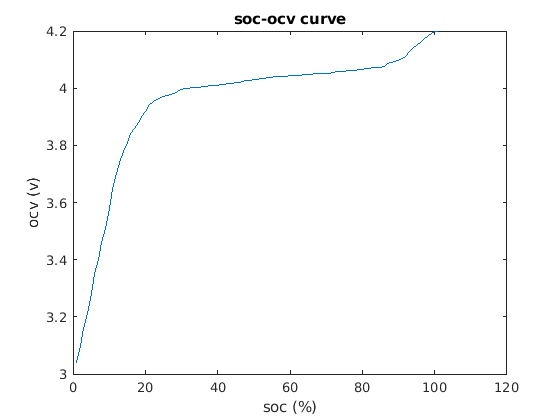

f1 = figure(1); clf;
plot(soc_ocv);
title("soc-ocv curve");
xlabel("soc (%)");
ylabel("ocv (v)");

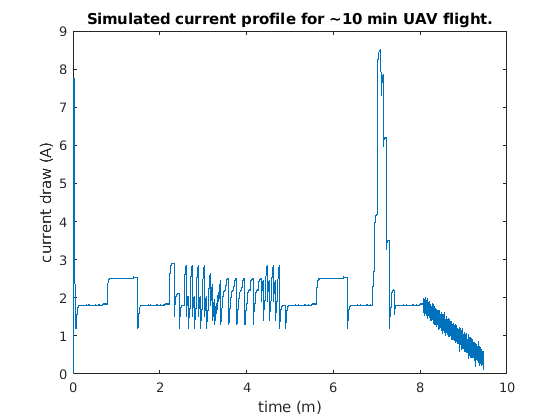

f2 = figure(2); clf; 
srate = 36;
t = (0:length(current) - 1) / srate / 60;
plot(t, current);
ylabel("current draw (A)");
xlabel("time (m)");
title("Simulated current profile for ~10 min UAV flight.");


Q   = battery.QParam(6); % total capacity in mAh
n   = battery.etaParam(6); % coulombic efficiency
M   = battery.MParam(6); % dynamic hysteresis volts factor
Mo  = battery.M0Param(6); % instant hysteresis volts factor
Ro  = battery.R0Param(6); % internal resistance
R   = [battery.RCParam(6,1)]; % diffusion / warburg impedence, pairs with C
C   = [battery.RCParam(6,2)]; % diffusion / warburg impedence, pairs with R
g   = battery.GParam(6);  % gamma, tunes decay in hysteresis
dt  = .01; % delta t

### State Variables

z   = state of charge (SOC)

        z[k+1] = z[k] - n[k]*dt*Io[k]

Ir  = current vector through each resistor in R

        Ir[k+1] = Arc*Ir[k] + Brc*Io[k]

h  = hysteresis

        h[k+1] = H[k]*h[k] + (H[k]-1)*sign(Io[k])

### Intermediates

if length(R) ~= length(C)
    error("R and C must be the same length");
end

- Arc, 'A' matrix of the state equation for Ir 

Arc = zeros(length(R));
for i = 1:length(R)
    Arc(i,i) = exp(-dt/(R(i)*C(i)));
end

- Brc, 'B' matrix of the state equation for Ir

Brc = zeros(length(R), 1);
for i = 1:length(R)
    Brc(i,1) = 1 - exp(-dt/(R(i)*C(i)));
end

- H, 'A' matrix (H-1 is 'B' matrix) of state equation for h, H is dynamic!

k = 1; % timestep
Io = .1; % current at time k
H(k) = exp(-abs((n(k)*Io(k)*g*dt)/Q))

H = 1.0000

### State equations

Io = current(1:floor(length(current)/2.5));
t2 = (0:length(Io) -1) / srate / 60;

z = 1.0; % soc
Ir = zeros(length(R), 1);
h = 0.0;
v = ones(length(Io));

soc = zeros(1, length(Io));
v = soc;
for i=1:length(Io)
    z_dot = z - ((n*dt)/Q)*Io(i);
    Ir_dot = Arc*Ir + Brc*Io(i);
    H = exp(-abs((n*Io(i)*g*dt)/Q));
    h_dot = H*h + (H-1)*sign(Io(i));
    z = z_dot;
    Ir = Ir_dot;
    h = h_dot;
    soc(i) = (z + 31.8816) /(1.0 + 31.8816);
    idx = ceil(soc(i)*100) +1;
    v(i) = (soc_ocv(idx) + Mo*sign(Io(i)) + M*h - sum(R*Ir) - Ro*Io(i));
  %  soc(i) = z;
end


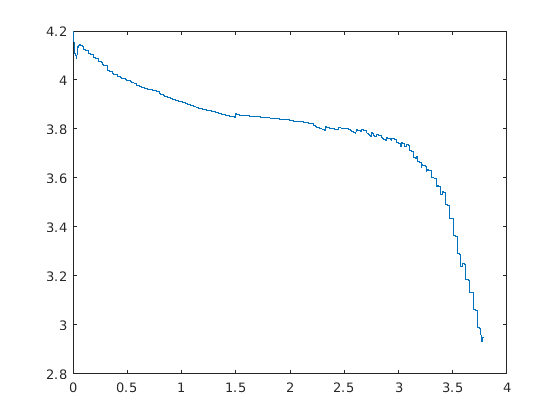

plot(t2, v);

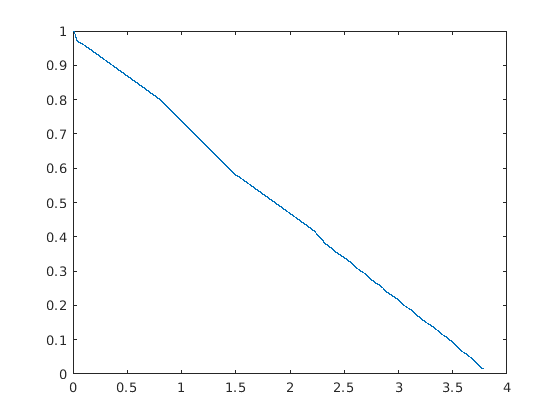

plot(t2, soc);

soc_ocv(76)

ans = 4.0605

soc_ocv(31)

ans = 3.8514

Y = zeros(50,1);
A = zeros(50,3);
for i=1:50
    a = randi([-10 10],1,3);
    A(i,:) = a;
    Y(i) = f(a);
end





function y = f(A)
    y = 4*A(1) + 2*A(2) - 6*A(3);

end

function [vk,rck,hk,zk,sik,OCV] = simCell(ik,T,deltaT,model,z0,iR0,h0)
  % Force data to be column vector(s)
  ik = ik(:); iR0 = iR0(:);
  
  % Get model parameters from model structure
  RCfact = exp(-deltaT./abs(getParamESC('RCParam',T,model)))';
  G = getParamESC('GParam',T,model);
  Q = getParamESC('QParam',T,model);
  M = getParamESC('MParam',T,model);
  M0 = getParamESC('M0Param',T,model);
  RParam = getParamESC('RParam',T,model);
  R0Param = getParamESC('R0Param',T,model);
  etaParam = getParamESC('etaParam',T,model);
  
  etaik = ik; etaik(ik<0) = etaParam*ik(ik<0);

  % Simulate the dynamic states of the model
  rck = zeros(length(RCfact),length(etaik)); rck(:,1) = iR0;
  for k = 2:length(ik)
    rck(:,k) = diag(RCfact)*rck(:,k-1) + (1-RCfact)*etaik(k-1);
  end
  rck = rck';
  zk = z0-cumsum([0;etaik(1:end-1)])*deltaT/(Q*3600); 
  if any(zk>1.1)
    warning('Current may have wrong sign as SOC > 110%');
  end
  
  % Hysteresis stuff
  hk=zeros([length(ik) 1]); hk(1) = h0; sik = 0*hk;
  fac=exp(-abs(G*etaik*deltaT/(3600*Q)));
  for k=2:length(ik)
    hk(k)=fac(k-1)*hk(k-1)-(1-fac(k-1))*sign(ik(k-1));
    sik(k) = sign(ik(k));
    if abs(ik(k))<Q/100, sik(k) = sik(k-1); end
  end
    
  % Compute output equation
  OCV = OCVfromSOCtemp(zk,T,model);
  
  vk = OCV - rck*RParam' - ik.*R0Param + M*hk + M0*sik;
end


